close all
clear
clc

mot.k = 2.8;
mot.T = 0.3;
mot.wn = 41.2;
mot.dl = 0.05;
s = tf('s');
P = minreal(mot.k / (s * (mot.T * s + 1)) * mot.wn^2 / (s^2 + 2 * mot.dl * mot.wn * s + mot.wn^2), 1e-6);
[numP, denP] = tfdata(P, 'v');

pid.Kp = 4.44;
pid.Ki = 10.13;
pid.Kd = 0.49;
pid.Tl = 0.03;
Ts = 0.005;

z = tf('z', Ts);
s = (z - 1) / Ts;
C = minreal(pid.Kp + pid.Ki / s + pid.Kd * s / (pid.Tl * s + 1), 1e-6);
[numC, denC] = tfdata(C, 'v');

umax = 10;
bit = 10;
res = 2000;
pulse2rad = 2 * pi / res;
deg2rad = pi / 180;
rad2deg = 180 / pi;

r.A = 60;
r.t = 0;

open_system("ex3_sim1m.slx")

set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "4")
sim("ex3_sim1m")

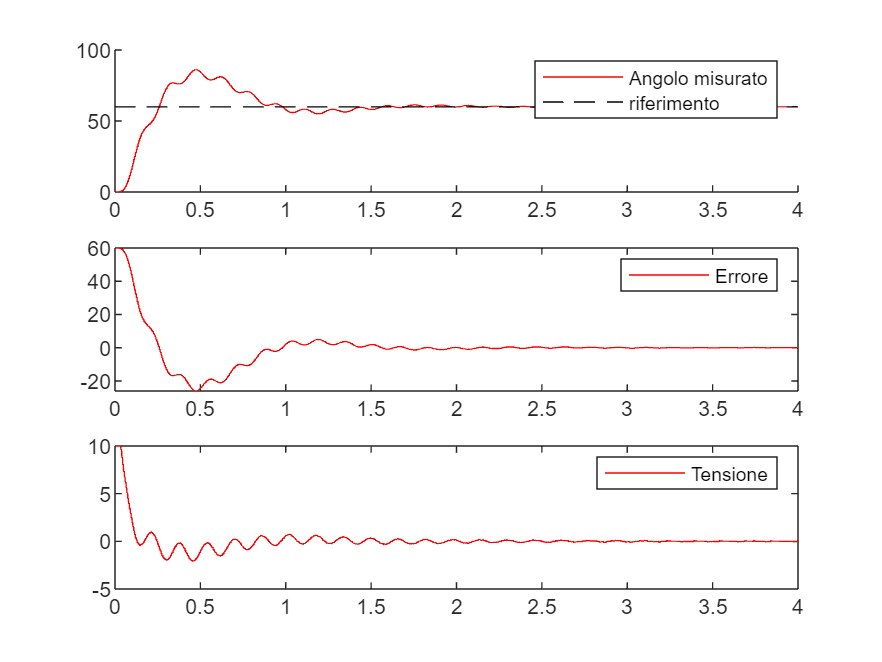

close all
figure(1)
subplot(3, 1, 1)
hold on
plot(sim1_res.time, sim1_res.signals(1).values, "r")
plot(sim1_res.time, sim1_res.signals(2).values, "k--")
legend("Angolo misurato", "riferimento")

subplot(3, 1, 2)
plot(sim1_res.time, sim1_res.signals(3).values, "r")
legend("Errore")

subplot(3, 1, 3)
plot(sim1_res.time, sim1_res.signals(4).values, "r")
legend("Tensione")

h.wz = mot.wn;
h.wp = 2 * pi * 50;
h.dz = mot.dl;
H = c2d(tf(h.wp^2 * [1 2 * h.dz * h.wz h.wz^2], h.wz^2 * [1 2 * h.wp h.wp^2]), Ts, "Tustin");
[numH, denH] = tfdata(H, 'v');

open_system("ex3_sim2m.slx")

set_param("ex3_sim2m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "4")
sim("ex3_sim2m")

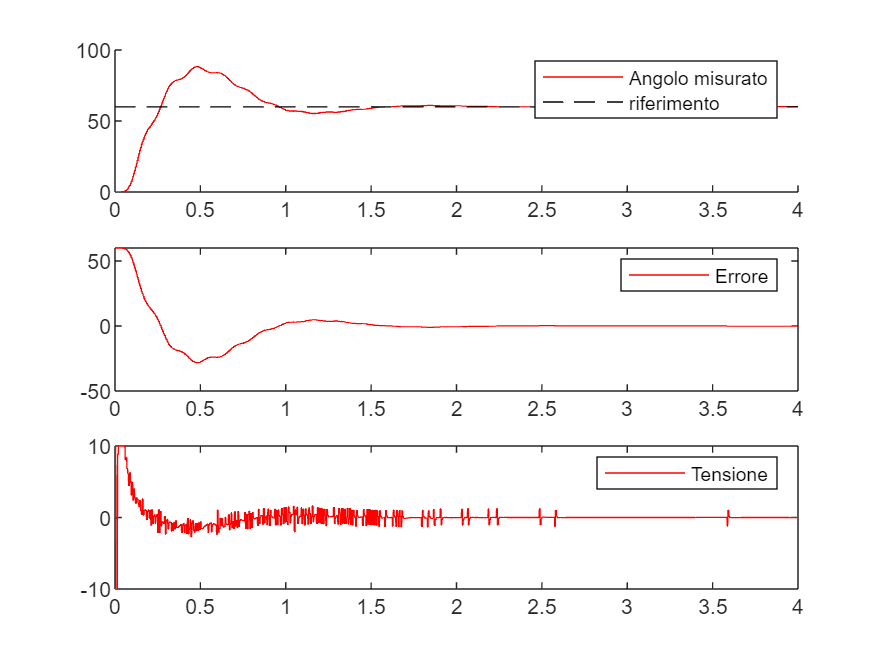

close all
figure(2)
subplot(3, 1, 1)
hold on
plot(sim2_res.time, sim2_res.signals(1).values, "r")
plot(sim2_res.time, sim2_res.signals(2).values, "k--")
legend("Angolo misurato", "riferimento")

subplot(3, 1, 2)
plot(sim2_res.time, sim2_res.signals(3).values, "r")
legend("Errore")

subplot(3, 1, 3)
plot(sim2_res.time, sim2_res.signals(4).values, "r")
legend("Tensione")

Nel secondo caso, le oscillazioni nel transitorio sono ridotte rispetto al primo caso.